# ** GRN Project 2**

Five gene regulatory network motifs are simulated in the code `GRNs_for_HW2.m`. These are:

- Direct negative feedback

- Indirect negative feedback

- Double negative feedback

- Incoherent feed-forward

- Repressilator

For most gene regulatory motifs, as an activating input is increased, the steady-state amount of protein increases gradually. The *biological function* of "ultrasensitivity" or "switch-like response" is a phenomena where the steady-state amount of protein increases slowly, then suddenly, then slowly again. 

# HW2 

Find at least one of the 5 network motifs listed above that produces a switch-like response. Plot the amount of protein as a function of input concentration, showing the switch-like graph.

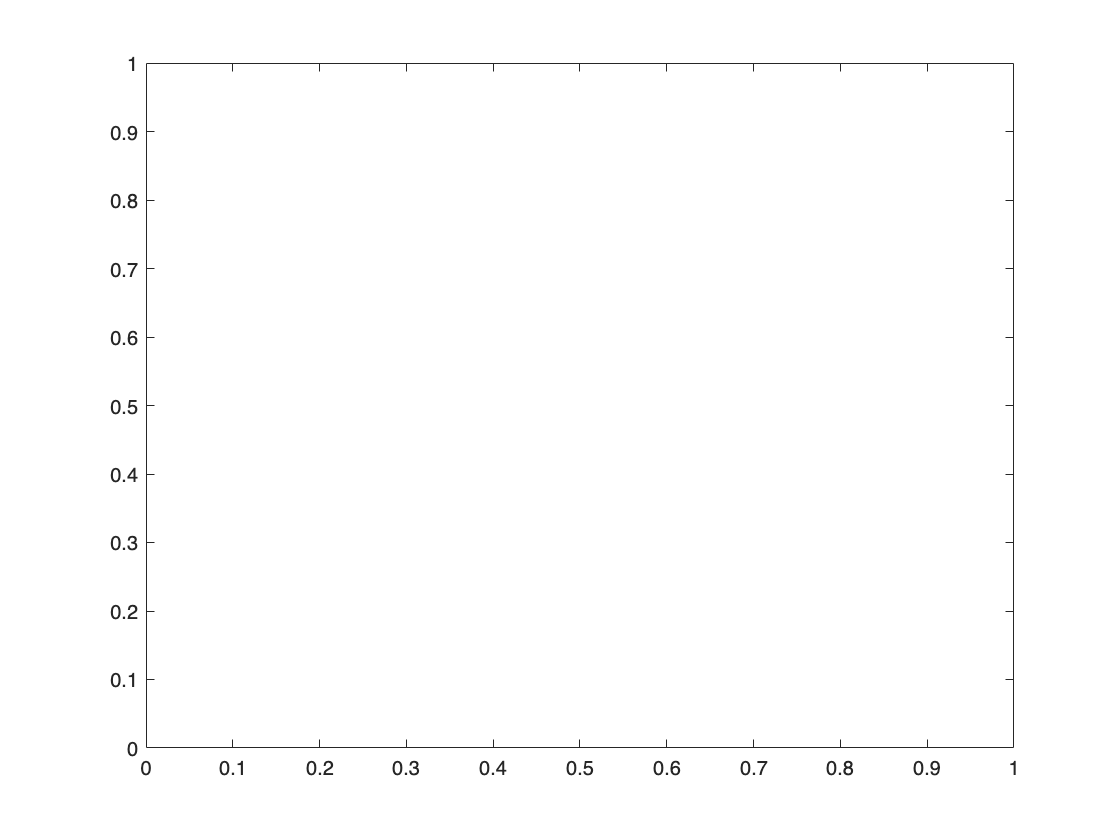

%gamma_ma = 1;
delta_ma = 0.05;
gamma_pa = 0.02;
delta_pa = 0.01;

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

figure; clf; hold on; box on;


for iParam = 1:numel(paramArray)

    Kaa = params{iParam}.Kaa; % Strength of inhibition of A by A 
    gamma_ma0 = params{iParam}.gamma_ma0; % Baseline production rate mRNA for A
    
    I = paramArray(iParam); % concentration of inhibitory transcription factor (uM) % EDIT for HW1
    C = 10; % concentration of activatory transcription factor (uM) % EDIT for HW1
    
    M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
                   +kon*I, -koff*I-kon*C,             0,   +koff;
                   +kon*C,             0,   -koff-kon*I,   +koff;
                        0,        +kon*C,         kon*I, -2*koff];

    gamma_ma =@(pa) gamma_ma0./(1+Kaa*pa);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pa) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;

    dxdt = @(t,x)[dmadt(x(1),x(2),t);
                  dpadt(x(1),x(2),t)];

    initialCondition = [0,0];

    [T, X] = ode45(dxdt, [0.0,600], initialCondition);

    subplot(1,numel(params),iParam); hold on; box on;
    axis square;
    set(gca,'xlim',[0,600], 'ylim',[0,80]);
    ylabel('RNA and Protein')   
    xlabel('Time (seconds)')
    plot(paramArray,X(:,1),'-g', 'linewidth', 3); % red for RNA
    plot(paramArray,X(:,2),'-', 'color', [0.5 0 1],'linewidth', 3); % purple

end

Undefined variable 'params'.